**PCS 130 Ohm's Law and Series Resistors**

Throughout this lab we will utilize matlab (live scripts) to aid in the procedure and analysis on the experiment performed. Live scripts allow us to execute code in line and organize the code and outputs in a notebook like fashion. For more detailed instructions on utilizing matlab live scripts see this link here: [https://www.mathworks.com/help/matlab/live-scripts-and-functions.html.](https://www.mathworks.com/help/matlab/live-scripts-and-functions.html.) **Be sure to save your .mlx files regularly to ensure no data is lost.**

For this experiment you will get examples on how to do various tasks in matlab such as:

- Generate a matrix of random values in a certain range.

- Practice performing calculations.

- Generate a line of best fit for experimental data.

**Generating Resistance Values **

In order to collect current data you need to vary the resistance values over a set interval for a given voltage set to your power supply. To generate a range of resistance of different resistance values you will use a function called randperm().

To ensure that your data is somewhat varied from other groups - take the last 4 digits from you and your partner's student number and add them together. This value will act as a seed so that your data can be reproduced.

%Change sn1 and sn2 to your partner's student numbers. If you are in a
%group of 3 use only 2 of 3 of your partner's student numbers. If you are
%working alone use only sn1. 
sn1 = 9097

sn1 = 9097

sn2 = 6315

sn2 = 6315

sn3 = 7437

sn3 = 7437

sn_combined = sn1+sn2+sn3

sn_combined = 22849

**Using randperm() to get the resistance values**

In the code block below you will use your sum from above to generate the resistance values to input on the decade resistor. Note that randperm(n,k) will generate k random numbers up to a value of n, for example: 

In the code block below set rng() to rng(sn_combined) to set the seed so that the random resistances generated will be reproducible every time you rerun the script. If the seed is not set you will have a different set of resistances each time!

The resistances vector has an additional function sort() wrapped around it. This will sort the random values generated by randperm for easier data collection. 

99 is added to the random values generated by randperm to set the lower bound to 100 as randperm generates values from 1 to 150 in this case.

%Setting a seed based on sn_combined so that the resistance values
%generated are reproducible.
rng(sn_combined)
%Create a column vector of 10 random values from 100 to 250 sorted in ascending
%order.
resistances = sort(randperm(150,10)+99)

resistances =    110   120   124   152   185   191   222   227   229   242


**Safe Voltage Calculation**

Before you start measuring current through the circuit, you will need to apply an electric potential (voltage) across the circuit. The electric potential is what causes the current to flow. In general, electrical components such as resistors have specific tolerances which allow their safe operation. On the decade box there are values that indicate the max current that the resistor inside can handle. 

In the code block below using Ohm's Law, I = V/R to solve for the **max voltage** you can apply to the circuit. Use the max current (I) indicated on the decade box for the knob of interest and the lowest resistance generated from your resistances matrix as I and R respectively. 

%Change the value of the variable "I" below to the max current indicated on
%the decade box for the knob of interest (i.e the knob where your max
%resistances values lie).
I=0.075

I = 0.0750

%Equation for Ohm's law but instead solving for voltage. Here we use the
%min of your resistance values.
V_max = I*min(resistances)

V_max = 8.2500

%Change the reduction factor below to a value between 0.4 and 0.75
reduction_factor = 0.6

reduction_factor = 0.6000

V_max = reduction_factor*V_max

V_max = 4.9500

**Obtaining current measurements**

Use the code block below to store your current measurements that you measure for each resistance on the decade resistor. To make things easier for plotting, ensure that the current is a column vector. 

current = [0.046 0.042 0.04 0.033 0.027 0.026 0.023 0.022 0.022 0.021]'

current =     0.0460
    0.0420
    0.0400
    0.0330
    0.0270
    0.0260
    0.0230
    0.0220
    0.0220
    0.0210


**Method 1: Generating a Line of Best Fit Using fitlm() (Recommended)**

To further analyze your current and resistance data, use the following code block below to generate a line of best fit. In the code block below, is a skeleton how to generate a line of best fit in Matlab. Indicated by comments (green text) are the elements of the code you need to edit in order to fit the data. 

**Note that if you are working on the analysis at home, your Matlab version will require the statistics and machine learning toolbox to use fitlm(). **If you do not have it installed, please see the instructions on installing add-ons [here](https://www.mathworks.com/help/matlab/matlab_env/get-add-ons.html).

% Generating linear fit of the data using the fitlm function with the
% y-intercept set to 0.
% Note you will need to replace the variables x and y with the
% appropriate data in order to get a linear fit. 

x = 1./resistances

x =     0.0091    0.0083    0.0081    0.0066    0.0054    0.0052    0.0045    0.0044    0.0044    0.0041


y = current

y =     0.0460
    0.0420
    0.0400
    0.0330
    0.0270
    0.0260
    0.0230
    0.0220
    0.0220
    0.0210


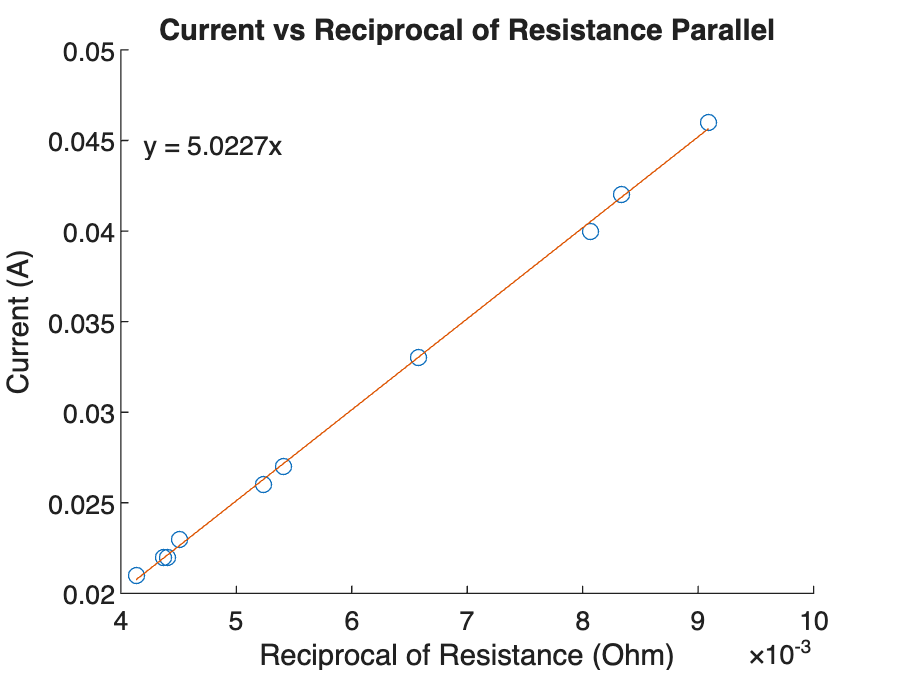


linear_model = fitlm(x,y,'Intercept',false);

% Generating y values based on the fit parameters and the x values. Think of the
% equation below as y = mx+b, where b = 0

y_fit_values = linear_model.Coefficients.Estimate(1)*x;
% Create a scatter plot.
scatter(x,y)
% Plotting the linear fit and scatter plot on one figure.
hold on
plot(x,y_fit_values)
% Add in chart elements such as the title, axes labels and fit equation.
title('Current vs Reciprocal of Resistance Parallel')
ylabel('Current (A)')
xlabel('Reciprocal of Resistance (Ohm)')
fit_equation = string(" y = " + linear_model.Coefficients.Estimate(1) + "x");
text(min(x),max(y_fit_values),fit_equation,"HorizontalAlignment","left","VerticalAlignment","top")
hold off 

**Method 2: Fitting using the Curve Fitter Application**

One way of performing the curve fitting in matlab is to use the curve fitting application. **Note that this will require the curve fitting toolbox.** If you do not have it installed, please see the instructions on installing add-ons [here](https://www.mathworks.com/help/matlab/matlab_env/get-add-ons.html). 

To open the curve fitting app, navigate to the apps tab on the top toolbar of the Matlab window and click on curve fitter. If the apps window is unresponsive type or if you are having issues opening the curve fitter, save your data and .mlx file and restart Matlab.

Once the Curve fitter is open follow the steps below to begin fitting:

- Select your x-data variable from the drop down menu

- Select your y-data variable from the drop down menu

- Once your data is selected, change the fit to the function. Hint: look at Ohm's law.